close all
clear
clc

准备工作

T = 4;
N = 1000;
[t,omg,FT,IFT] = prefourier([-T/2,T/2],N,[-16*pi,16*pi],1000);

定义矩形脉冲和三角脉冲

f1 = (t>=0&t<1);
f2 = (t>=0&t<1).*(1-t);

直接计算卷积

xtemp = T/N*conv(f1,f2);
x = xtemp(N/2:N/2+N-1);

直接计算相关

ytemp = T/N*xcorr(f1,f2);
y = ytemp(N/2:N/2+N-1);

用卷积定理计算卷积

x1 = IFT*((FT*f1).*(FT*f2));

用相关定理计算相关

y1 = IFT*((FT*f1).*conj(FT*f2));

绘图

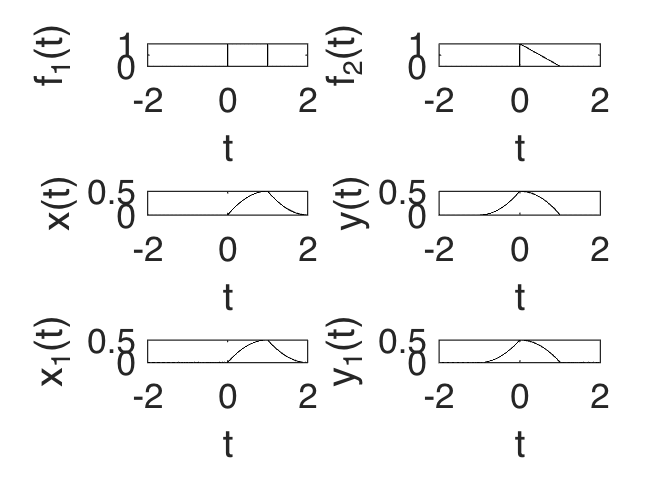

figure;
dat = {f1,f2,x,y,x1,y1};
lab = {'f_1(t)','f_2(t)','x(t)','y(t)','x_1(t)','y_1(t)'};
for n = 1:6
    subplot(3,2,n), hold on, box on;
    plot(t,real(dat{n}),'k-');
    set(gca,'FontSize',14,'XLim',[-2 2]);
    if n>=3
        set(gca,'YLim',[0 0.5]);
    end
    xlabel('t');
    ylabel(lab{n});
end